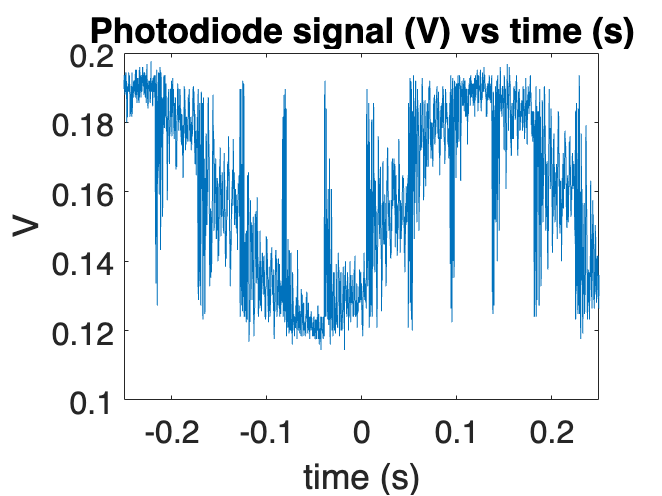

plot(t,V)   
title("Photodiode signal (V) vs time (s)")
xlabel("time (s)")
ylabel("V")
ax = gca;
ax.FontSize = 16;

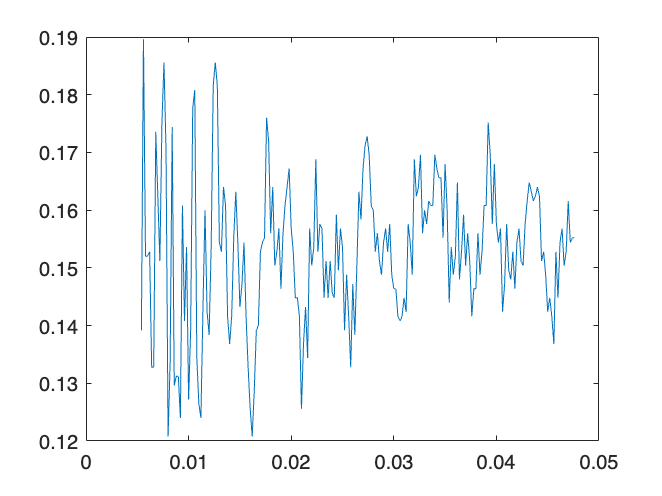

dt = t(2)-t(1);
% t1 = 3.436;
% t2 = 3.708; 

t1 = 0.0056;
t2 = 0.0478;
delta_t = t2-t1;

start = 1 + floor((t1-t(1))/dt);
stop = 1 + floor((t2-t(1))/dt);
V_reduced = V(start:stop);
t_reduced = t(start:stop);
plot(t_reduced, V_reduced)

% V_reduced_mov = movmean(V_reduced, 10);
% plot(t_reduced, V_reduced_mov);
V_rms = rms(V_reduced);
display(V_rms);

V_rms = 0.1534

t_avg = mean(t_reduced);
display(t_avg);

t_avg = 0.0265

display(delta_t);

delta_t = 0.0422

% t = zeros(1,60);
% V = zeros(1,60);

plot(tavg,deltaT)
title("delta t = t2-t1 (s) vs time (s)")
xlabel("time (s)")
ylabel("delta t = t2-t1 (s)")
ax = gca;
ax.FontSize = 16;